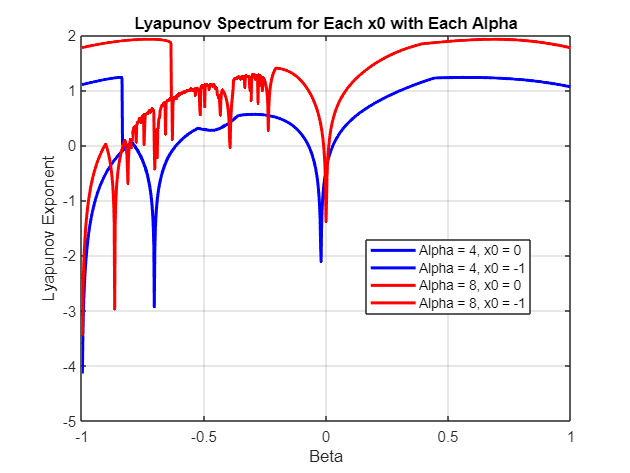

% Define parameters
alpha_values = [4, 8];
beta_values = linspace(-1, 1, 1000); % Values of Beta

% Initialize Lyapunov exponents array
num_alphas = length(alpha_values);
num_x0 = 2; % Two initial conditions: x0 = 0 and x0 = -1
lyapunov_exponents = zeros(length(beta_values), num_x0, num_alphas);

for alpha_idx = 1:num_alphas
    alpha = alpha_values(alpha_idx);

    for beta_idx = 1:length(beta_values)
        beta = beta_values(beta_idx);

        % Initialize variables
        x0_values = [0, -1];
        num_iterations = 1000;
        sum_log_derivative = zeros(1, num_x0);

        for x0_idx = 1:num_x0
            x0 = x0_values(x0_idx);
            x = x0;

            for n = 1:num_iterations
                % Gaussian map iteration
                x  = exp(-alpha*x^2) + beta;

                % Compute the derivative of the map
                map_derivative = -2 * alpha * x * exp(-x^2);

                % Update the sum of logarithmic derivatives
                sum_log_derivative(x0_idx) = sum_log_derivative(x0_idx) + log(abs(map_derivative));
            end

            % Compute the average logarithmic derivative for this x0
            average_log_derivative = sum_log_derivative(x0_idx) / num_iterations;

            % Store Lyapunov exponent
            lyapunov_exponents(beta_idx, x0_idx, alpha_idx) = average_log_derivative;
        end
    end
end

% Plot the Lyapunov spectrum for each x0 with each alpha
figure;
colors = ['b', 'r']; % Colors for Alpha = 4 and Alpha = 8
legend_labels = cell(1, num_x0 * num_alphas);

for alpha_idx = 1:num_alphas
    for x0_idx = 1:num_x0
        plot(beta_values, lyapunov_exponents(:, x0_idx, alpha_idx), colors(alpha_idx), 'LineWidth', 2);
        hold on;
        legend_labels{(alpha_idx - 1) * num_x0 + x0_idx} = ['Alpha = ', num2str(alpha_values(alpha_idx)), ', x0 = ', num2str(x0_values(x0_idx))];
    end
end

xlabel('Beta');
ylabel('Lyapunov Exponent');
title('Lyapunov Spectrum for Each x0 with Each Alpha');
legend(legend_labels, 'Location', 'best');
grid on;